clear all
nu = 8e4;
c = 335; %Скорость звука
optimal_d = 0.95*c/(2*nu); %Рассчёт оптимального расстояния между датчиками (коэффициент должен лежать в пределах от 0 до 1)
xn = [-3*optimal_d, -2*optimal_d, 0, optimal_d, 2*optimal_d, 3*optimal_d]; %Координаты микрофонов в МН с неэквидистантным расположением датчиков
rotate_D = 90; % Значение угла, на котором находится главный лепесток ДН

N = size(xn,2); %Количество элементов в массиве
w = 1/N; %Комплексный весовой коэффициент каждого элемента
phi_limits = [1,180]; %Границы ДН по азимутальному углу в градусах [от,до]
phi_step = 1; %Шаг изменения угла ДН по азимутальному углу

phi = phi_limits(1):1:phi_limits(2); %Массив со всеми исследуемыми углами
phi_c = cosd(phi); %Массив с косинусами всех исследуемых углов
phi_c = phi_c - cosd(rotate_D); %Учитываем желаемый угол поворота ДН

Выравниваем количество элементов в массиве углов и массиве микрофонов, после чего создаём необходимые для правильного умножения матрицы

if(size(phi,2)<N)
    phi_c = [phi_c zeros(1,size(xn,2)-size(phi,2))];
end
phi_c = [phi_c' zeros(size(phi,2),size(phi,2)-1)];
xn = cat(1,xn,zeros(size(phi,2)-1,N));

Считаем и строим диаграмму направленности

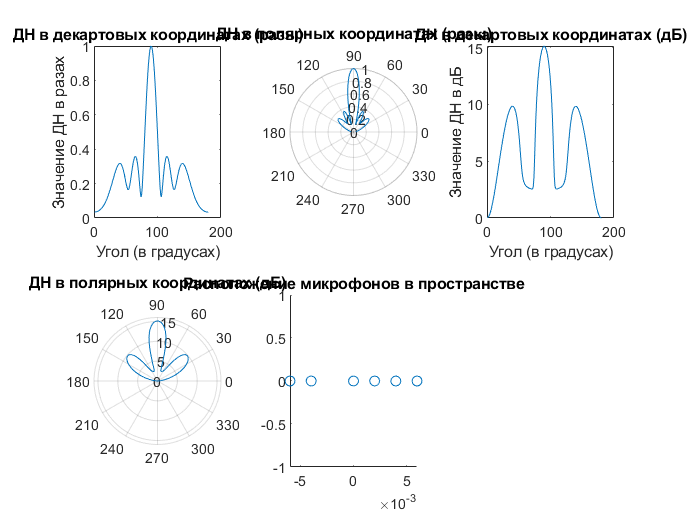

D = transpose(sum((w*(exp(phi_c*1j*2*pi*(1/c)*xn)).^nu),2)); %Считаем ДН
theta = linspace(1,phi_limits(2),phi_limits(2)); %Здесь и далее строим ДН
theta_radians = deg2rad(theta);
D_db = 10*log10(D);

if (xn(1,2)-xn(1,1)>(c/(2*nu)))
    warning_msg = "Внимание! Происходит наложение ДН!"
end

figure(1);
subplot(2,3,1); %Декартовы координаты и разы
plot((phi_limits(1):1:phi_limits(2)),abs(D));
title("ДН в декартовых координатах (разы)");
xlabel("Угол (в градусах)");
ylabel("Значение ДН в разах");

subplot(2,3,2); %Полярные координаты и разы
polarplot(theta_radians,abs(D));
title("ДН в полярных координатах (разы)");

subplot(2,3,3); %Декартовы координаты и дБ
plot((phi_limits(1):1:phi_limits(2)),-abs(D_db)+max(abs(D_db)))
title("ДН в декартовых координатах (дБ)");
xlabel("Угол (в градусах)");
ylabel("Значение ДН в дБ");

subplot(2,3,4); %Полярные координаты и дБ
polarplot(theta_radians,-abs(D_db)+max(abs(D_db)));
title("ДН в полярных координатах (дБ)");

subplot(2,3,5);
scatter(xn(1,1:N),zeros(1,size(xn(1,1:N),2)));
title("Расположение микрофонов в пространстве");